# Direct Channel Estimation - Phase 1

**Based on the paper:** Channel Estimation for Intelligent Reflecting Surface Assisted Multiuser Communications: Framework, Algorithms, and Analysis 

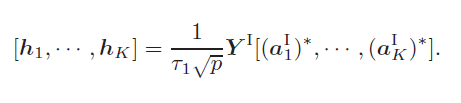 or

 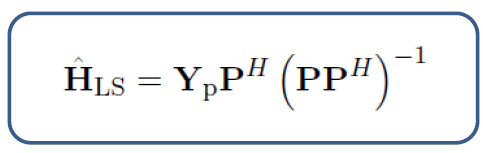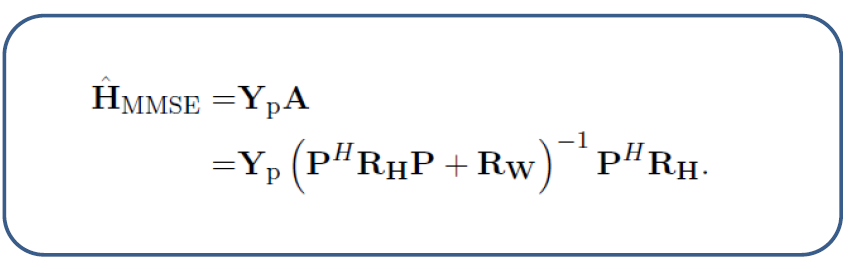

function [channel, MSE] = channelDirectEstimation(sys, channel, estimation, wo_noise, pwr)

    H = channel.H;
        
    noise_dbm = estimation.noise_dbm;
    T0 = estimation.T0_min;
    
    K = sys.n_tx;
    M = sys.n_rx;
    PWR = sys.PWR;
    
    % Power Normalization -----------------------------------
    sigma2_nest = (10^(noise_dbm/10));
    sigma2_s = PWR(pwr);
    
    %% ===============Phase I===========================
    F0_temp=dftmtx(T0);
    pilots = F0_temp(1:K,:)*sqrt(sigma2_s); % pilots
    pilotsH = pilots';
    
    noise = sqrt(sigma2_nest/2)*(randn(M,T0)+1j*randn(M,T0));
    Y0 = H*pilots+noise;
    
    if wo_noise
        %% With noise --------------------------------------
        A = inv(pilotsH*diag(channel.Hkloss)*pilots + sigma2_nest*eye(T0))*pilotsH*diag(channel.Hkloss);
        H_est = Y0*A;
   
    else
        %% Without noise -----------------------------------
        factor = 1/(T0*sqrt(sigma2_s));
        H_est = factor*Y0*pilotsH;
    end

    channel.H_est = H_est;
    modH2 = H(:)'*H(:);
    MSE=(H_est(:)-H(:))'*(H_est(:)-H(:))/modH2;
end